# Homodimer PMFs

We create the homodimers for D, F, A, and G residues by eliminating the extra residues from the DFAG molecule and applying the bonds between GLY-COA, any sidechain bonds/angles/dihedrals being left the same as they were in DFAG, and any angles/dihedrals containing multiple residues as the same potential for whichever potential contained *most* of the participating beads in the initial DFAG potential tables.

We open the initial 10 ns runs that may not be converged yet to have a look.

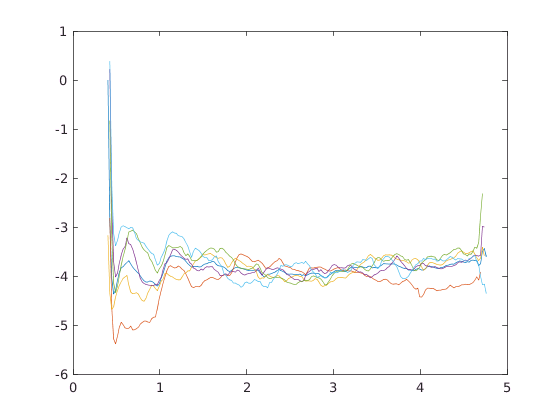

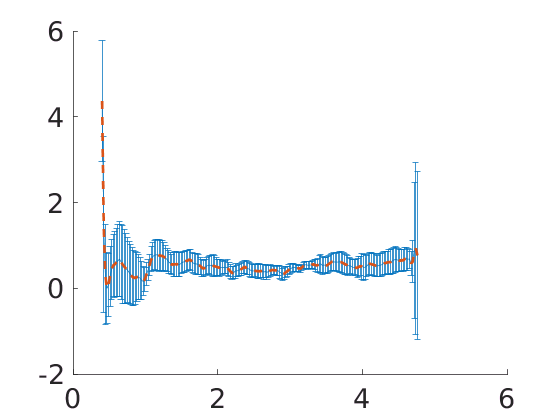

%access appropriate functions
addpath('/home/rachael/Analysis_and_run_code/analysis/coarsegraining/model_assessment');
addpath('/home/rachael/Analysis_and_run_code/analysis/coarsegraining/patchy_particles/helper_functions');
%investigate PMFs
fbaseD = '/home/rachael/cluster/scratch/ramansbach/orient_restrain_mon_PMF/arom_line_restrain/homoD/5_umbrella';
fbaseF = '/home/rachael/cluster/scratch/ramansbach/orient_restrain_mon_PMF/arom_line_restrain/homoF/5_umbrella';
fbaseA = '/home/rachael/cluster/scratch/ramansbach/orient_restrain_mon_PMF/arom_line_restrain/homoA/5_umbrella';
fbaseG = '/home/rachael/cluster/scratch/ramansbach/orient_restrain_mon_PMF/arom_line_restrain/homoG/5_umbrella';
tstart = 0;
tinterval = 2000;
tend = 10000;
remove_entropic = 0;
[profD,errsD] = run_block_PMFs(fbaseD,tstart,tinterval,tend,remove_entropic,[2 4]);

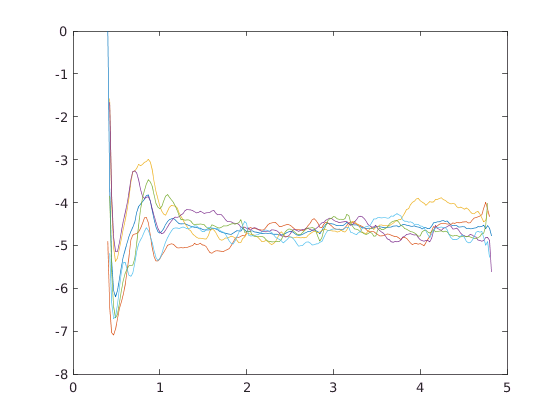

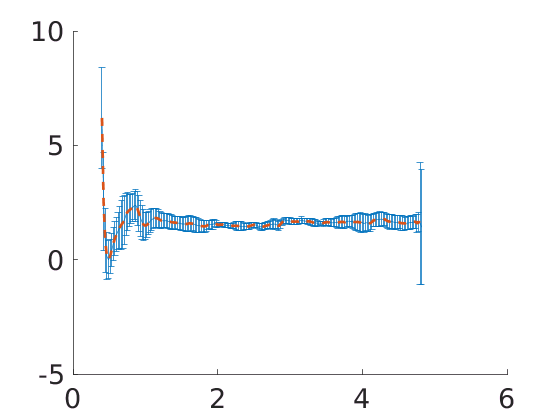

[profF,errsF] = run_block_PMFs(fbaseF,tstart,tinterval,tend,remove_entropic,[2 4]);

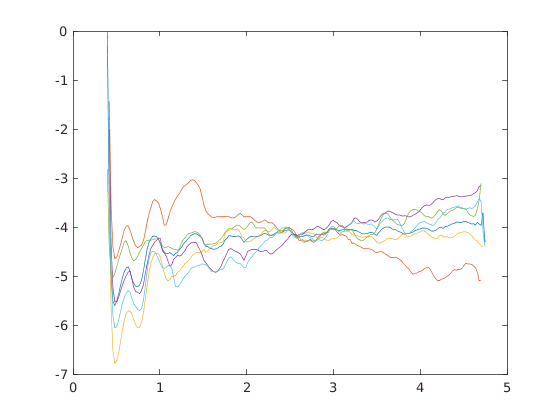

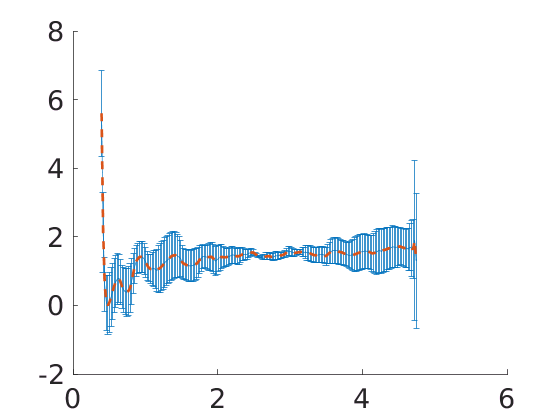

[profA,errsA] = run_block_PMFs(fbaseA,tstart,tinterval,tend,remove_entropic,[2 3.5]);

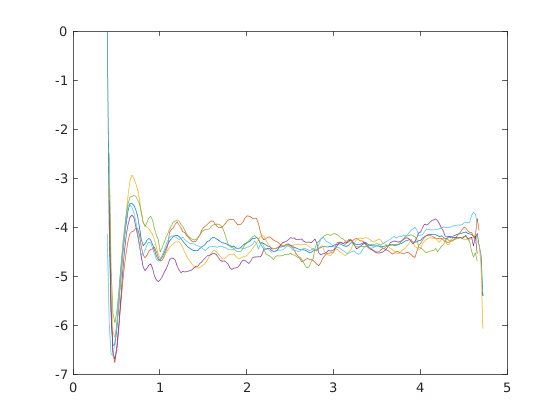

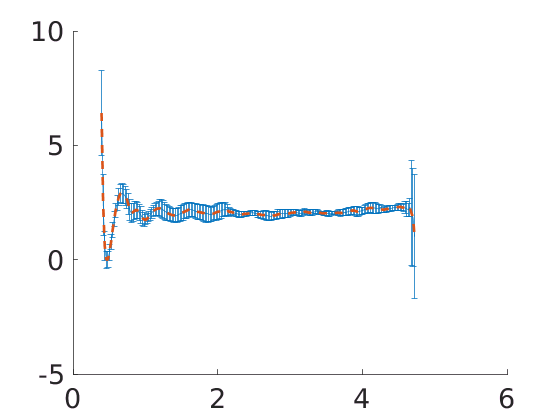

[profG,errsG] = run_block_PMFs(fbaseG,tstart,tinterval,tend,remove_entropic,[2 4]);

## Get approximate changes

Find the difference between the minimum and the value at 3.5 nm

x = 3.5;
indD = find(abs(profD(:,1)-x)==min(abs(profD(:,1)-x)));
indF = find(abs(profF(:,1)-x)==min(abs(profF(:,1)-x)));
indA = find(abs(profA(:,1)-x)==min(abs(profA(:,1)-x)));
indG = find(abs(profG(:,1)-x)==min(abs(profG(:,1)-x)));
dFD = profD(indD,2) - min(profD(:,2));
dFF = profF(indF,2) - min(profF(:,2));
dFA = profA(indA,2) - min(profA(:,2));
dFG = profG(indG,2) - min(profG(:,2));
iminD = find(profD(:,2)==min(profD(:,2)));
iminF = find(profF(:,2)==min(profF(:,2)));
iminA = find(profA(:,2)==min(profA(:,2)));
iminG = find(profG(:,2)==min(profG(:,2)));
sdFD = sqrt(errsD(iminD,1)^2+errsD(indD,1)^2);
sdFF = sqrt(errsF(iminF,1)^2+errsF(indF,1)^2);
sdFA = sqrt(errsA(iminA,1)^2+errsA(indA,1)^2);
sdFG = sqrt(errsG(iminG,1)^2+errsG(indG,1)^2);
fprintf('The delta F for D is ~%f +/- %f',dFD,sdFD);

The delta F for D is ~0.534670 +/- 0.849134

fprintf('The delta F for F is ~%f +/- %f',dFF,sdFF);

The delta F for F is ~1.644236 +/- 0.852653

fprintf('The delta F for A is ~%f +/- %f',dFA,sdFA);

The delta F for A is ~1.434256 +/- 0.895533

fprintf('The delta F for G is ~%f +/- %f',dFG,sdFG);

The delta F for G is ~2.032585 +/- 0.394087

fprintf('The total dF for DFAG is ~%f +/- %f',dFD+dFF+dFA+dFG,sqrt(sdFD^2+sdFF^2+sdFA^2+sdFG^2));

The total dF for DFAG is ~5.645747 +/- 1.550912

This means the dF for DFAG ranges from ~4 to ~7.2, while the most attractive dF measured here would be DGGG, which has a maximum at 8.5.

It seems reasonable to measure within this window, or a little past it, so 2, 4, 6, 8, 10 are all reasonable measurements.  If we want to avoid extras, 2, 6, 10 spans the window; 4 and 8 can be added in later as necessary.